# 双闭环晶闸管不可逆直流调速系统

数据来源：指导书📖

sheets=sheetnames("exprData.xlsx");
%额定电压220v 电流1.6a，转速1600r/min
% nN=1600;
IN=1.6;

## 闭环控制特性曲线

根据实验数据，画出闭环控制特性曲线

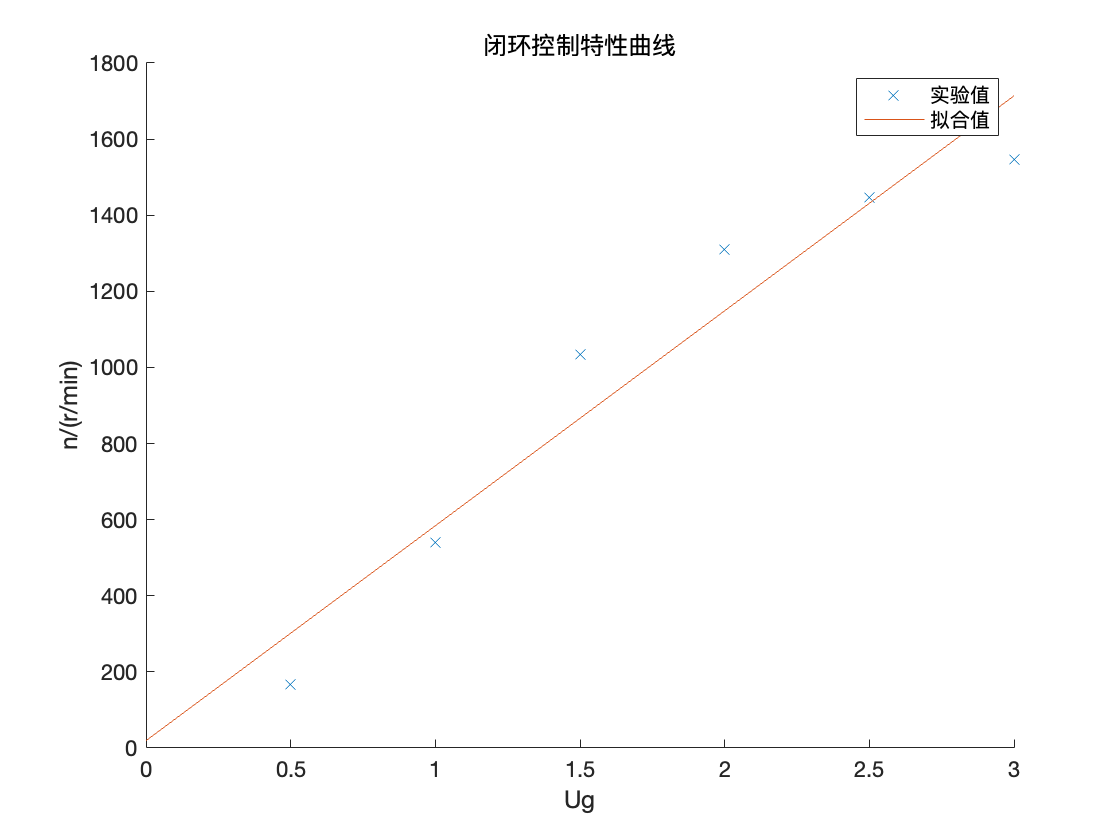

data=readmatrix("exprData.xlsx","Sheet",sheets(8));
n=data(1,2:end);
I=data(2,2:end);
p=polyfit(I,n,1);
x=[0,I];
figure();hold on;
f = polyval(p,x); 
plot(I,n,'x');
plot(x,f,'-');
legend('实验值','拟合值');
title("闭环控制特性曲线");
ylabel('n/(r/min)');
xlabel('Ug');

## 闭环机械特性

根据实验数据，画出闭环机械特性，并计算静差率。

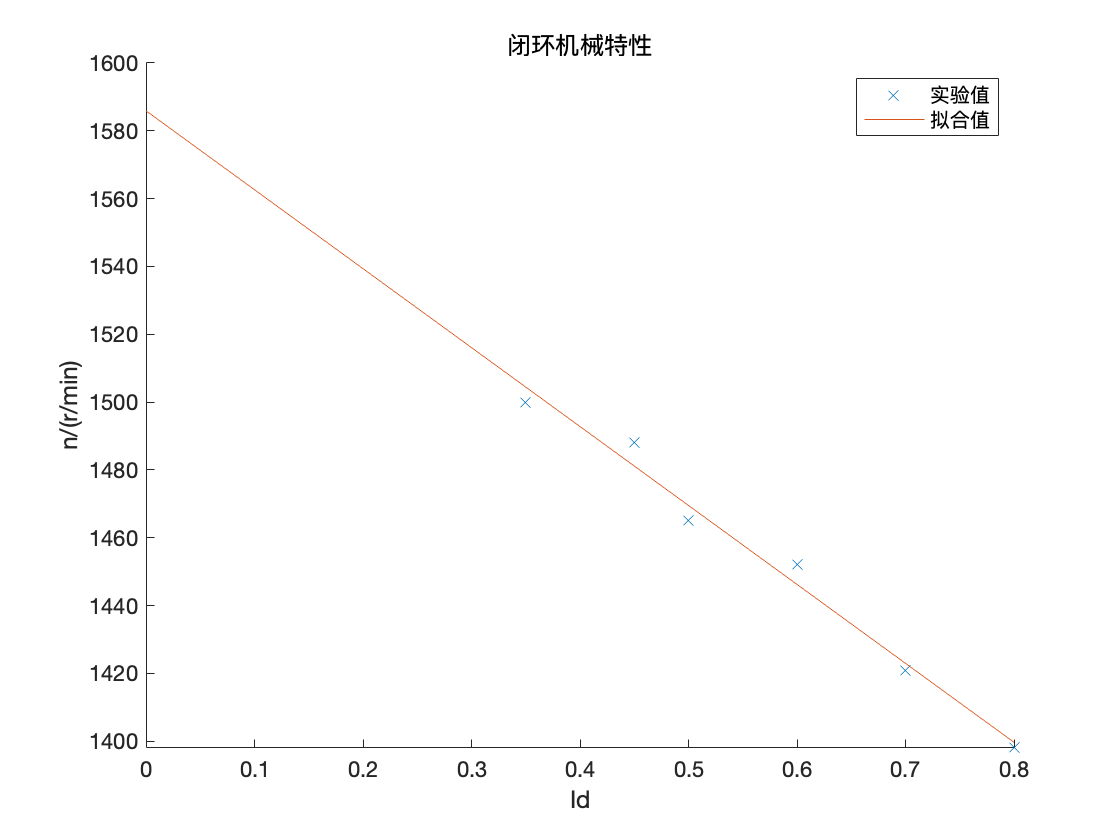

data1=readmatrix("exprData.xlsx","Sheet",sheets(7));
n1=data1(1,2:end);
I1=data1(2,2:end);
p1=polyfit(I1,n1,1);
x1=[0,I1];
figure();hold on;
f1 = polyval(p1,x1); 
plot(I1,n1,'x');
plot(x1,f1,'-');
legend('实验值','拟合值');
title("闭环机械特性");
ylabel('n/(r/min)');
xlabel('Id');

计算系统静差率$s=\frac{\Delta n_N}{n_0}$

n0=f1(1);
nN=polyval(p1,IN);
s1=(n0-nN)/n0;
fprintf("闭环系统n0=%.3f,s=%.3f%%",n0,s1*100);

闭环系统n0=1585.904,s=23.484%

## 开环机械特性

根据实验数据，画出系统开环机械特性，计算静差率，并与闭环机械特性进行比较。

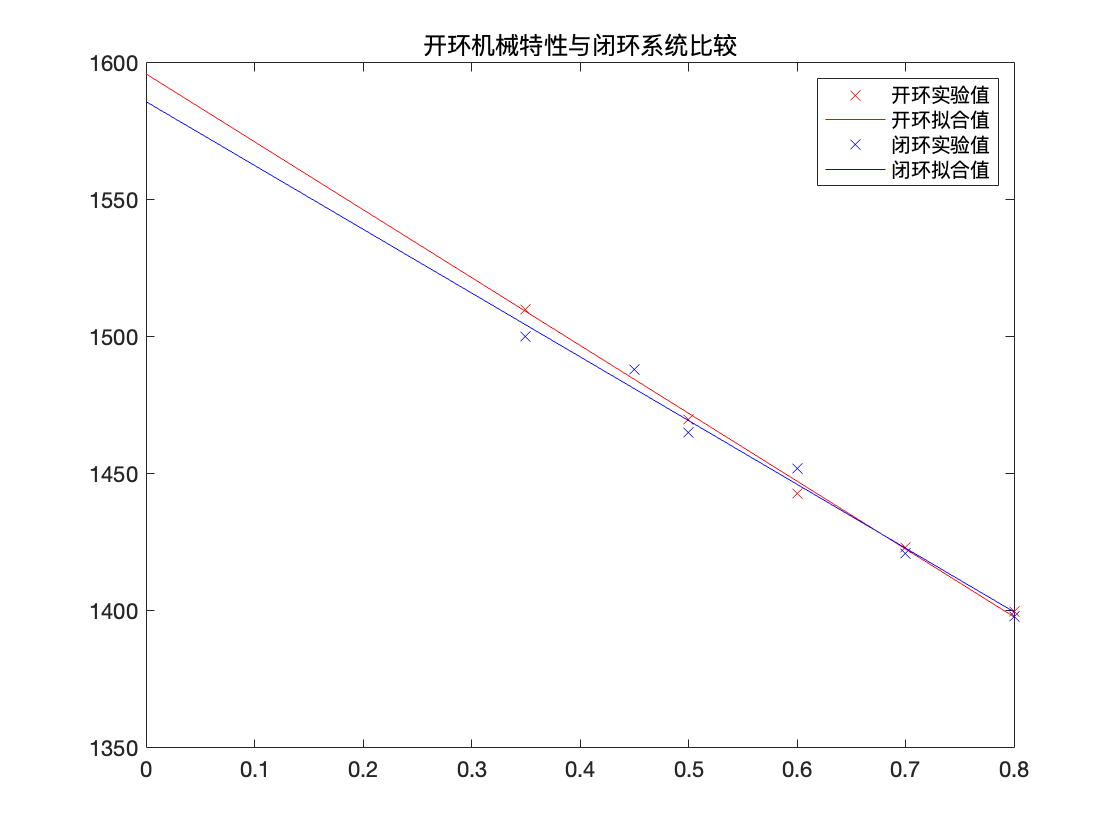

data2=readmatrix("exprData.xlsx","Sheet",sheets(6));
n2=data2(1,2:end);
I2=data2(2,2:end);
p2=polyfit(I2,n2,1);
x2 =[0,I2];
f2 = polyval(p2,x2); 
figure();
plot(I2,n2,'rx',x2,f2,'r-',I1,n1,'bx',x1,f1,'b-');
legend('开环实验值','开环拟合值','闭环实验值','闭环拟合值');
title("开环机械特性与闭环系统比较");

计算比较开闭环系统静差率

n0=f2(1);
nN=polyval(p2,IN);
s2=(n0-nN)/n0;
fprintf("开环系统n0=%.3f,s=%.3f%%\n闭环系统n0=%.3f,s=%.3f%%" ...
    ,f2(1),s2*100,f1(1),s1*100);

开环系统n0=1596.036,s=24.833%
闭环系统n0=1585.904,s=23.484%